data = readtable('data.csv');
vars = data.Properties.VariableNames;
x = data.Variables;
X = x(:,1:9)'

X =   101.5237  111.8239  110.4415  110.3444  109.4546  108.5316  111.4637  110.6705  113.5153  113.9429  104.5357  105.1560  112.1103  113.0446  111.9032  115.4154  116.5226  116.4105  113.3417  112.6773  113.9820  100.9461  113.4500  114.1335  103.5780   95.1417  114.6207   96.2362  114.6472  104.3551  100.0923  101.3628  105.9447  103.9490  104.5958  108.2571  113.0117   98.6141  114.2861  103.7040  105.0514  104.7695  113.5267  112.1585  110.2957  104.6319  113.8145  113.3016  113.8561  113.1075
  100.5987   92.5719  108.1901  110.5864  105.9778  106.5348   98.9525   99.3395   85.9582   88.0378   93.1648  103.7618   93.0238   92.2507   96.8108   98.9869   97.1273   98.6510   91.0990   97.3924   90.9484   87.4409   88.6180   75.0855   87.2609   87.3621   89.7310   86.9143   88.6788   89.8813   91.1211   93.9185   89.5282   81.0163   79.1350   99.7995   91.7559   95.3005   88.0970   93.6672   92.5509   89.2016   84.7880   90.1955   87.4606   78.0982   87.2352   87.4964   94.7382   95

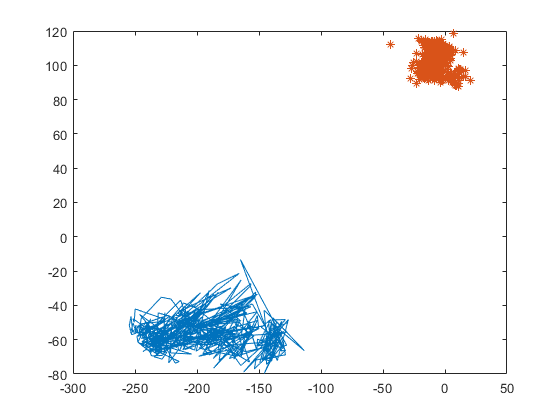

m = mean(X,2);
Xcen = X-m*ones(1,500);
C = 1/500*Xcen*Xcen';
[V,D] = eig(C);
[~,inx] = sort(diag(D),'descend');
Wpca = V(:,inx(1:4));
Xdim = Wpca'*X;
figure;
plot(Xdim(1,:),Xdim(2,:),Xdim(3,:),Xdim(4,:),'*')